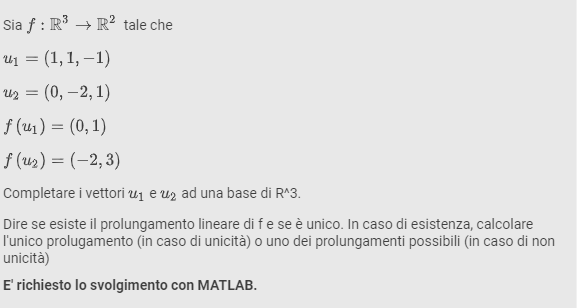

u1 = [1 1 -1]

u1 =      1     1    -1


u2 = [0 -2 1]

u2 =      0    -2     1


fu1=[0,1]

fu1 =      0     1


fu2=[-2 3]

fu2 =     -2     3


Per completare ad una base di R^3 considero un qualunque vettore a 3 componenti della base canonica:

u3 = [1 0 0]

u3 =      1     0     0


E verifico se u1, u2, u3 sono linearmente indipendenti:

B3 = [u1 ; u2 ;u3]

B3 =      1     1    -1
     0    -2     1
     1     0     0


rank(B3)

ans = 3

Sono linearmente indipendenti quindi formano una base di R^3. In questo caso esistono infiniti prolungamenti lineari dal momento che l'immagine dell'ultimo vettore che va a completare la base (u3) viene scelta a piacere.

fu3 = [1,1]     %scelgo arbitrariamente fu3

fu3 =      1     1


Dato che l'insieme di vettori trovati costituisce una base dello spazio vettoriale, il generico vettore di R^3 puó essere scritto come combinazione lineare:

syms a b c
xyx = a*u1 + b*u2 + c*u3

$$xyx = \left(\begin{array}{ccc} a+c & a-2\,b & b-a \end{array}\right)$$

Da cui deriva il seguente sistema lineare:


$$\begin{cases}
a+c=x \\
a-2b =y \\
b-a = z


\end{cases}$$


Considero la matrice completa associata e la riduco a scalini per ottenere un sistema minimale equivalente:

syms x y z
A = [1 0 1 x ; 1 -2 0 y ; -1 1 0 z]

$$A = \left(\begin{array}{cccc} 1 & 0 & 1 & x\\ 1 & -2 & 0 & y\\ -1 & 1 & 0 & z \end{array}\right)$$


S =A 

$$S = \left(\begin{array}{cccc} 1 & 0 & 1 & x\\ 1 & -2 & 0 & y\\ -1 & 1 & 0 & z \end{array}\right)$$

S(2,:) = S(2,:) - S(1,:)

$$S = \left(\begin{array}{cccc} 1 & 0 & 1 & x\\ 0 & -2 & -1 & y-x\\ -1 & 1 & 0 & z \end{array}\right)$$

S(3,:) = S(3,:) + S(1,:)

$$S = \left(\begin{array}{cccc} 1 & 0 & 1 & x\\ 0 & -2 & -1 & y-x\\ 0 & 1 & 1 & x+z \end{array}\right)$$

S(3,:) = 2*S(3,:) + S(2,:)

$$S = \left(\begin{array}{cccc} 1 & 0 & 1 & x\\ 0 & -2 & -1 & y-x\\ 0 & 0 & 1 & x+y+2\,z \end{array}\right)$$

Da cui il sistema minimale:


$$\begin{cases} 

a+c=x \\
-2b -c =y-x \\
c =x+y+2z

\end{cases}$$


Che ha per soluzioni:

a=-y-2*z

$$a = -y-2\,z$$

b=-y-z

$$b = -y-z$$

c=x+y+2*z

$$c = x+y+2\,z$$

Che sono le componenti rispetto alla base canonica considerata. Le sostituisco nella combinazione lineare precedentemente considerata:

xyz = a*u1 + b*u2 +c*u3

$$xyz = \left(\begin{array}{ccc} x & y & z \end{array}\right)$$

Da cui ottengo il relativo prolungamento lineare:

f(xyz)=a*fu1 +b*fu2 +c*fu3

$$f(x, y, z) = \left(\begin{array}{cc} x+3\,y+4\,z & x-3\,y-3\,z \end{array}\right)$$

Si tratta di uno dei tanti prolungamenti lineari costruibili... in questo caso il prolungamento é stato trovato a partire da $f\left(1,0,0\right)=\left(1,1\right)$